clc
clear
close all

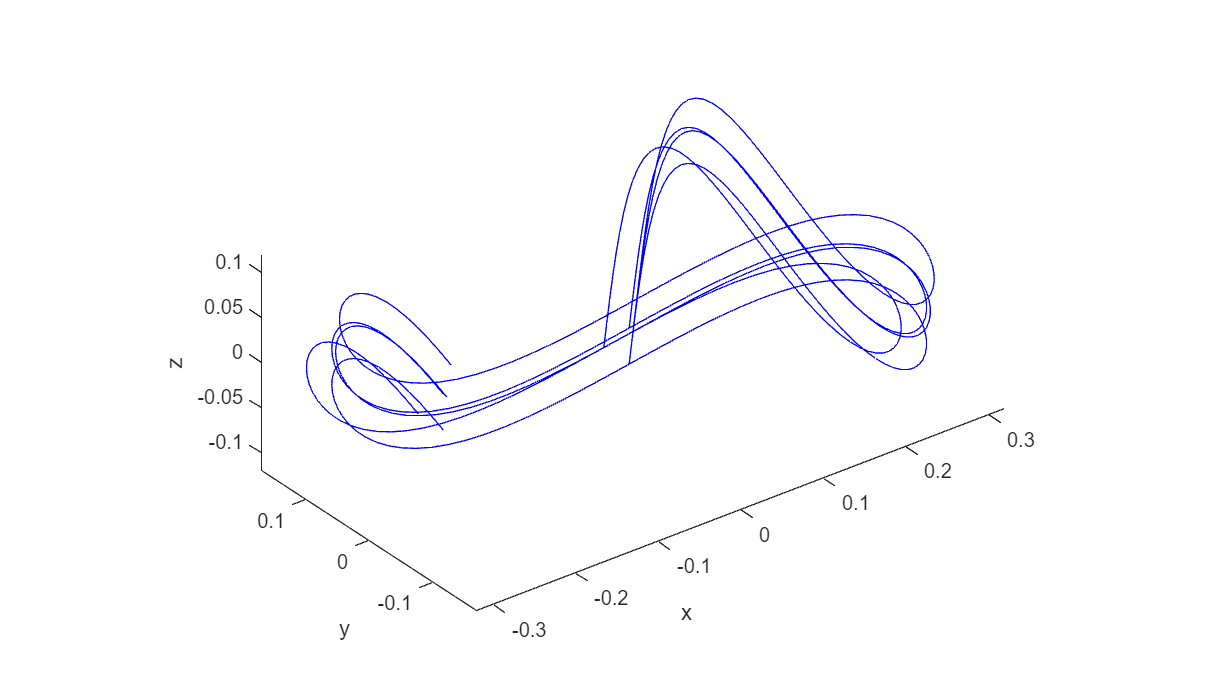

time = linspace(0, 15, 100);
x1 = [];
y1 = [];
z1 = [];

for i = 1 : length(time)
    x1(i) = 0.3 * sin(time(i)/3);
    y1(i) = 0.3 * sin(time(i)/3) * cos(time(i)/3);
    z1(i) = 0.1 * sin(time(i));
end
x2 = x1 - 0.02;
y2 = y1 - 0.02;
z2 = z1 - 0.02;

x3 = x1 + 0.02;
y3 = y1 + 0.02;
z3 = z1 + 0.02;

x4 = x1 - 0.02;
y4 = y1 - 0.02;
z4 = z1 + 0.02;

x5 = x1 - 0.02;
y5 = y1 + 0.02;
z5 = z1 - 0.02;

x6 = x1 + 0.02;
y6 = y1 - 0.02;
z6 = z1 - 0.02;

set1 = linspace(1, length(x1), length(x1));
set2 = linspace(1, length(x2), length(x2));
set3 = linspace(1, length(x3), length(x3));
set4 = linspace(1, length(x4), length(x4));
set5 = linspace(1, length(x5), length(x5));
set6 = linspace(1, length(x6), length(x6));

Data(1,:) = [set1, set2, set3, set4, set5, set6];
Data(2,:) = [x1, x2, x3, x4, x5, x6];
Data(3,:) = [y1, y2, y3, y4, y5, y6];
Data(4,:) = [z1, z2, z3, z4, z5, z6];

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];
sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);

[~,locs] = findpeaks(Data(1,:));
start = 1;
for i = 1: length(locs)
    indexes = [start, locs(i)];
    x = Data(2, start:locs(i));
    y = Data(3, start:locs(i));
    z = Data(4, start:locs(i));
    plot3(x, y, z, 'b');
    hold on

    % Update start
    start = locs(i) + 1;
end
axis equal
xlabel('x');
ylabel('y');
zlabel('z');

Definition of the number of components used in GMM.

nbStates = 8;
nbVar = size(Data,1);
nbAxis = nbVar - 1

nbAxis = 3

Training of GMM by EM algorithm, initialized by k-means clustering.

[Priors, Mu, Sigma] = EM_init_kmeans(Data, nbStates);
[Priors, Mu, Sigma] = EM(Data, Priors, Mu, Sigma);

Use of GMR to retrieve a generalized version of the data and associated constraints. A sequence of temporal values is used as input, and the expected distribution is retrieved.

time = linspace(0, 100, 100);
[expData, expSigma] = GMR(Priors, Mu, Sigma, time, [1], [2:nbVar]);

Plot of the data

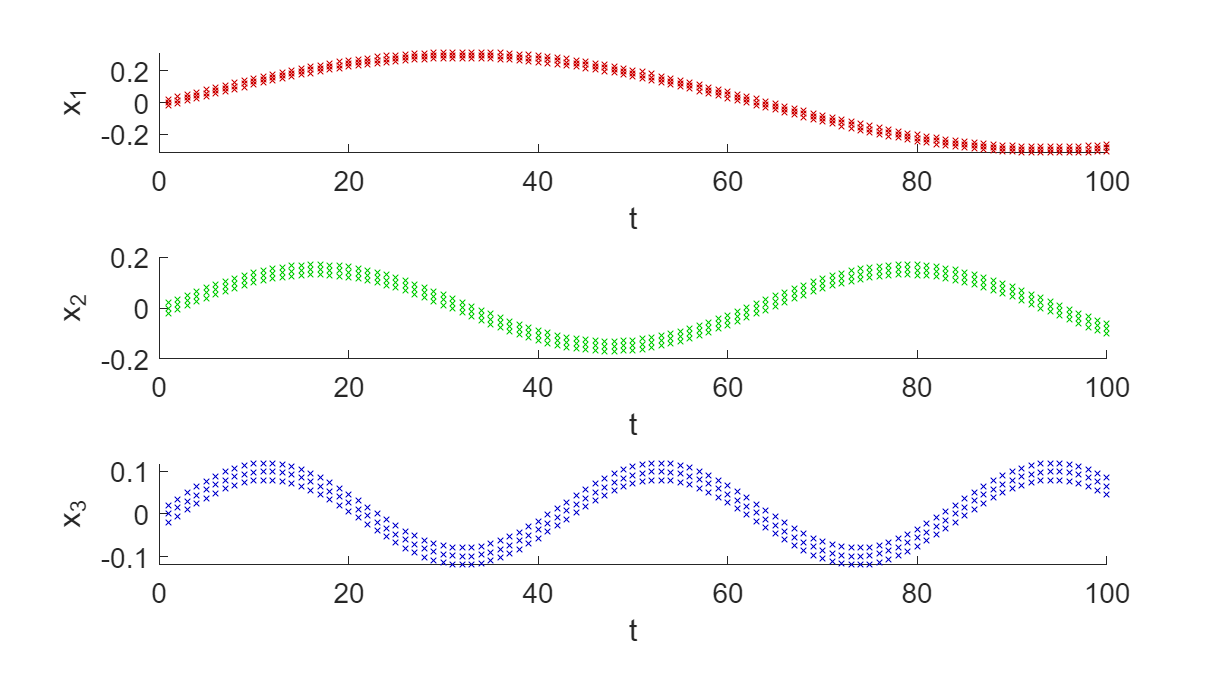

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

color = {[.8, 0, 0], [0, .8, 0], [0, 0, .8]};

%plot 1D
for n=1:nbAxis
    sPlot = subplot((nbAxis), 1, n);
    set(sPlot,'FontSize',14);
    hold on;

    plot(Data(1,:), Data(n+1,:), 'x', 'markerSize', 4, 'color', cell2mat(color(n)));
    xlabel('t');
    ylabel(['x_' num2str(n)]);
end


fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

%plot 2D
sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);

if (nbAxis == 2)
    plot(Data(2,:), Data(3,:), 'x', 'markerSize', 4);
    xlabel('x_1');
    ylabel('x_2');
elseif (nbAxis == 3)
    [~,locs] = findpeaks(Data(1,:));
    start = 1;
    for i = 1: length(locs)
        indexes = [start, locs(i)];
        x = Data(2, start:locs(i));
        y = Data(3, start:locs(i));
        z = Data(4, start:locs(i));
        plot3(x, y, z, 'b');
        hold on
    
        % Update start
        start = locs(i) + 1;
    end
    axis equal
    xlabel('x');
    ylabel('y');
    zlabel('z');
end

Plot of the GMM encoding results

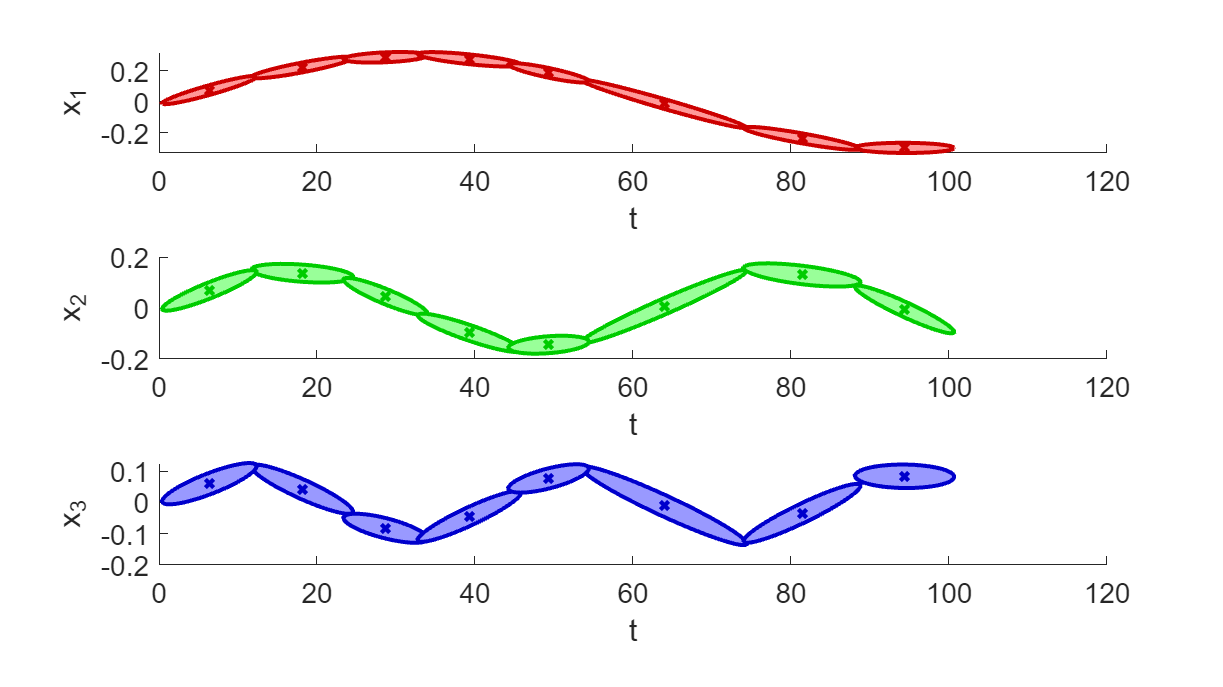

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

%plot 1D
for n=1:nbAxis
    sPlot = subplot((nbAxis), 1, n);
    set(sPlot,'FontSize',14);
    hold on;

    plotGMM(Mu([1,n+1],:), Sigma([1,n+1],[1,n+1],:), cell2mat(color(n)), 1);
    xlabel('t');
    ylabel(['x_' num2str(n)]);
end

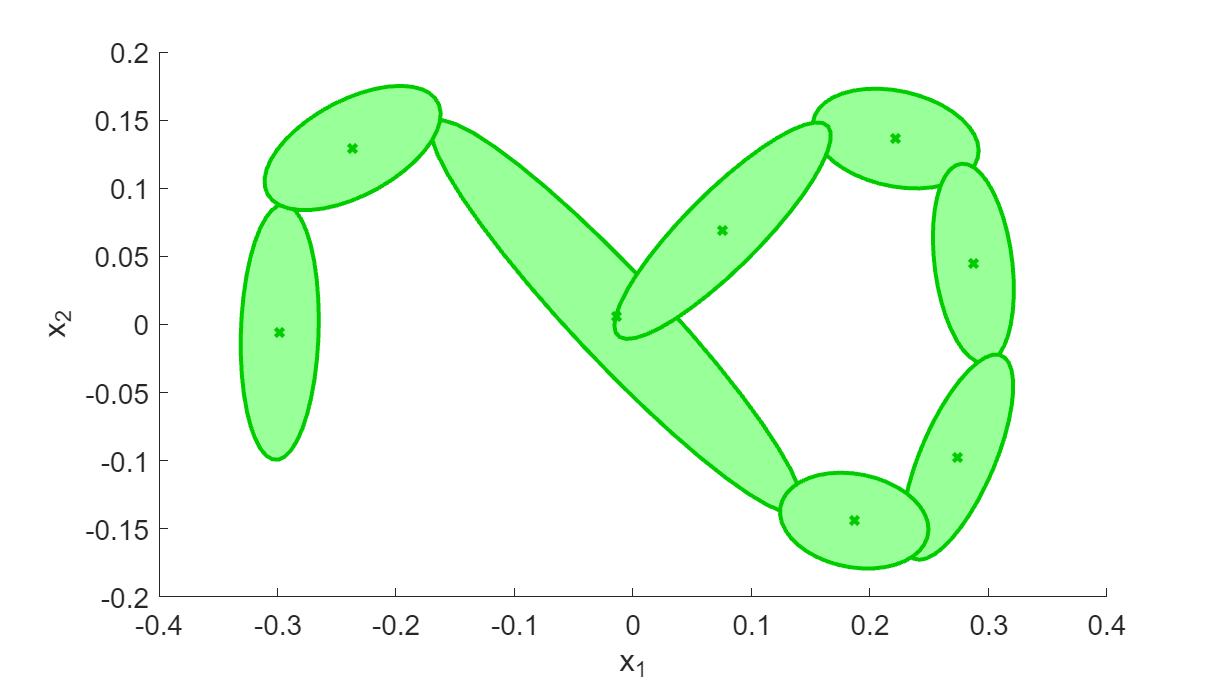


fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

%plot 2D
sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);
hold on;


plotGMM(Mu([2,3],:), Sigma([2,3],[2,3],:), [0 .8 0], 1);
xlabel('x_1');
ylabel('x_2');

Plot of the GMR regression results

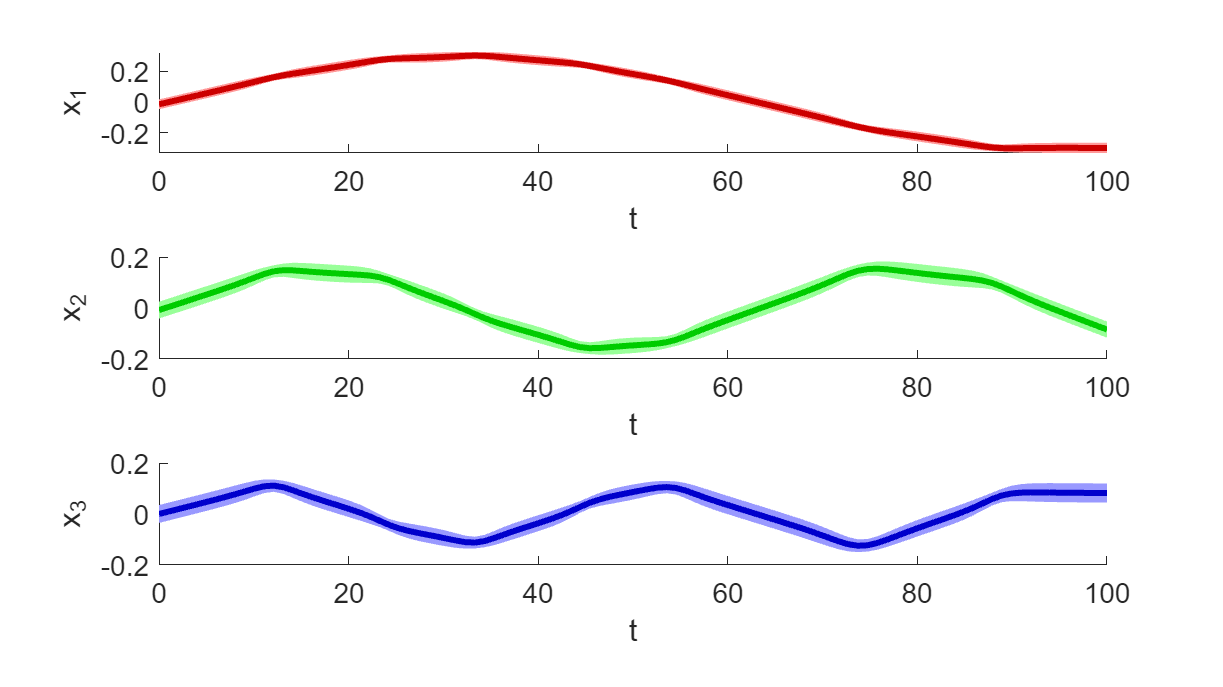

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

%plot 1D
for n=1:nbAxis
    sPlot = subplot((nbAxis), 1, n);
    set(sPlot,'FontSize',14);
    hold on;

    plotGMM([time; expData(n,:)], expSigma(n,n,:), cell2mat(color(n)), 3);
    xlabel('t');
    ylabel(['x_' num2str(n)]);
end

Mu = expData;
Sigma = expSigma;

for j=1:length(Mu)
    x_max(j) = Mu(1,j) + sqrtm(3.*Sigma(1,1,j));
    x_min(j) = Mu(1,j) - sqrtm(3.*Sigma(1,1,j));

    y_max(j) = Mu(2,j) + sqrtm(3.*Sigma(1,1,j));
    y_min(j) = Mu(2,j) - sqrtm(3.*Sigma(1,1,j));

    z_max(j) = Mu(3,j) + sqrtm(3.*Sigma(1,1,j));
    z_min(j) = Mu(3,j) - sqrtm(3.*Sigma(1,1,j));
end

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);

line = [Mu(:,1:end) Mu(:,end:-1:1)];
variance = [
    x_max(1:end), x_min(end:-1:1);
    y_max(1:end), y_min(end:-1:1);
    z_max(1:end), z_min(end:-1:1)];

for r=1: 3
    for c=1: 3
        temp_x_max = zeros(1, length(Mu));
        temp_y_max = zeros(1, length(Mu));
        temp_z_max = zeros(1, length(Mu));
        temp_x_min = zeros(1, length(Mu));
        temp_y_min = zeros(1, length(Mu));
        temp_z_min = zeros(1, length(Mu));

        for i=1:length(Mu)
            temp_x_max(i) = Mu(1,i) + sqrtm(3.*Sigma(r,c,i));
            temp_x_min(i) = Mu(1,i) - sqrtm(3.*Sigma(r,c,i));

            temp_y_max(i) = Mu(2,i) + sqrtm(3.*Sigma(r,c,i));
            temp_y_min(i) = Mu(2,i) - sqrtm(3.*Sigma(r,c,i));

            temp_z_max(i) = Mu(3,i) + sqrtm(3.*Sigma(r,c,i));
            temp_z_min(i) = Mu(3,i) - sqrtm(3.*Sigma(r,c,i));
        end
        temp_variance = [
            temp_x_max(1:end), temp_x_min(end:-1:1);
            temp_y_max(1:end), temp_y_min(end:-1:1);
            temp_z_max(1:end), temp_z_min(end:-1:1)];
        
        fill3(temp_variance(1,:), temp_variance(2,:), temp_variance(3,:), 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'LineWidth', 2)
        hold on
    end
end

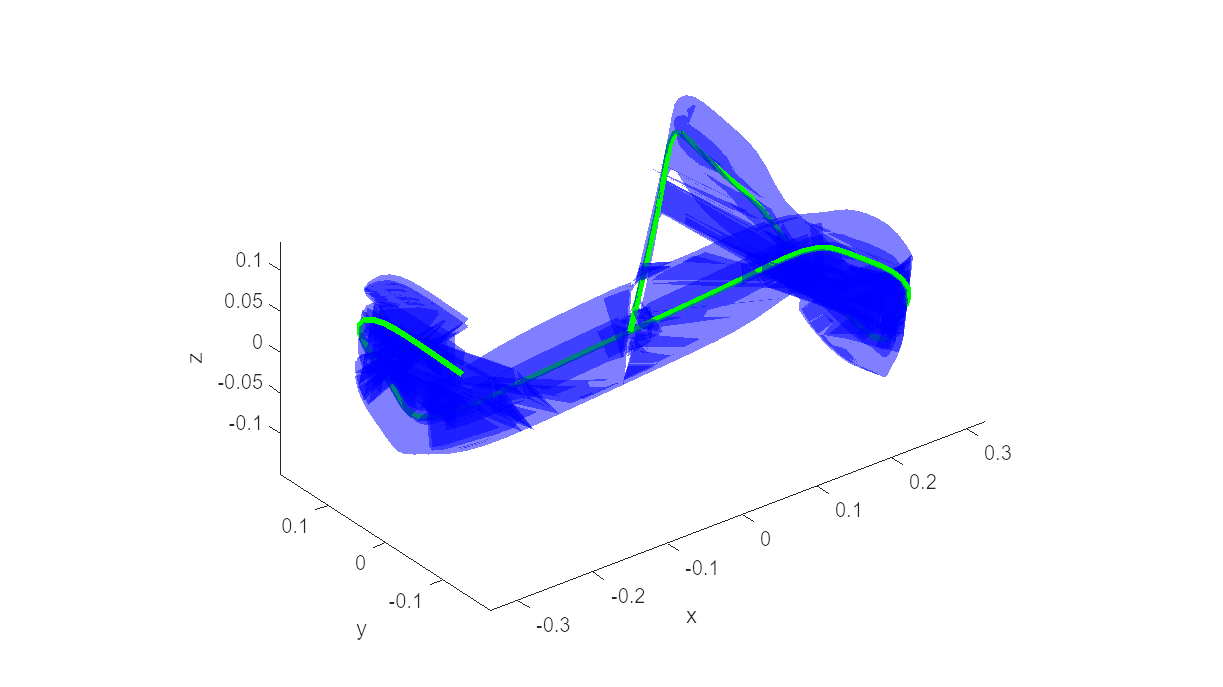

plot3(Mu(1,:), Mu(2,:), Mu(3,:), '-', 'lineWidth', 3, 'color', 'g');
axis equal
xlabel('x');
ylabel('y');
zlabel('z');

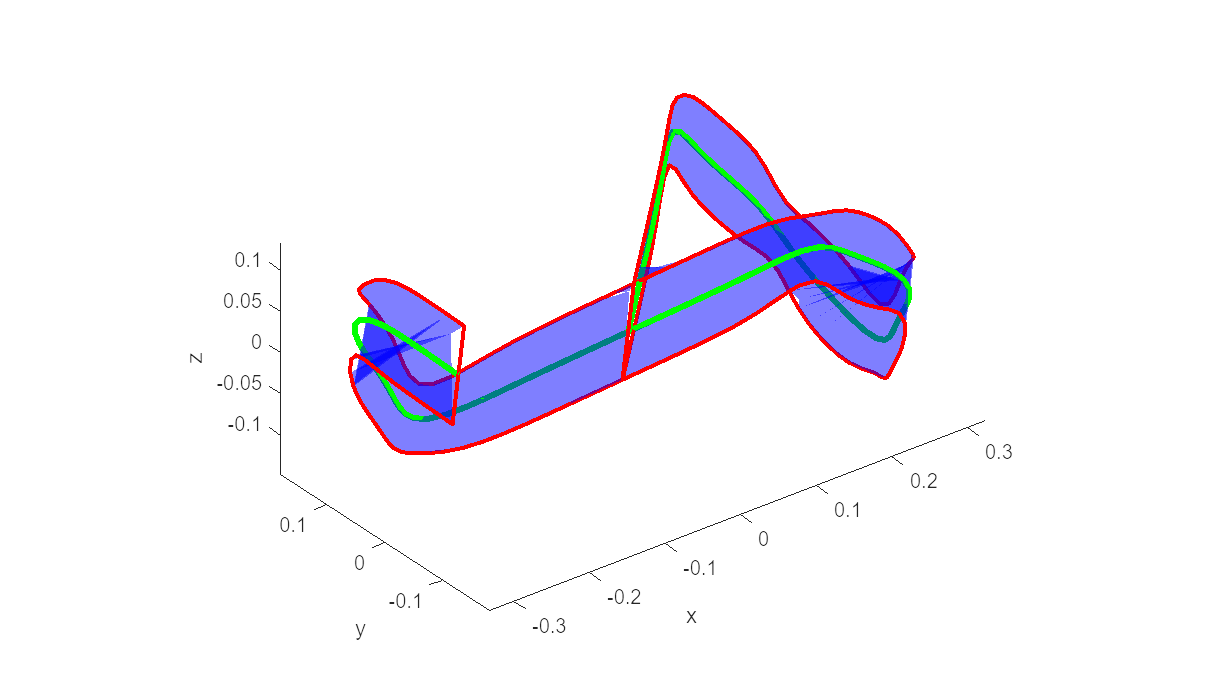

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);

fill3(variance(1,:), variance(2,:), variance(3,:), 'b', 'FaceAlpha', 0.5, 'EdgeColor', 'r', 'LineWidth', 2)
hold on
plot3(Mu(1,:), Mu(2,:), Mu(3,:), '-', 'lineWidth', 3, 'color', 'g');
axis equal
xlabel('x');
ylabel('y');
zlabel('z');

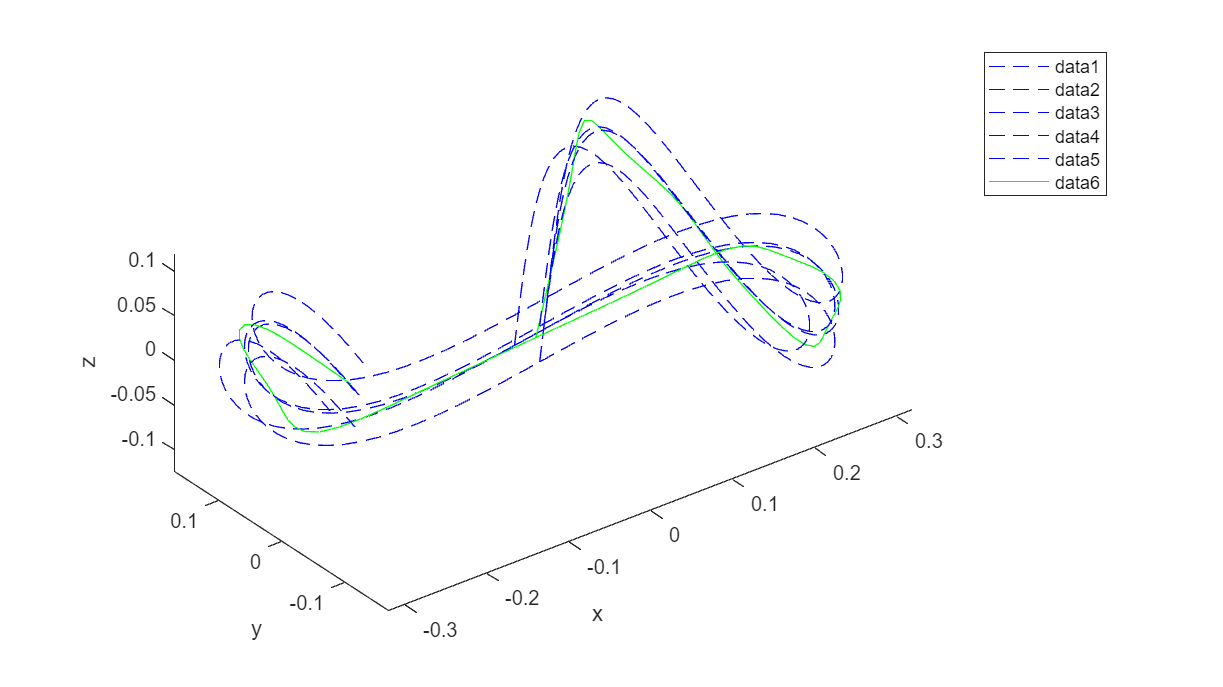

fig = figure("WindowState","maximized","Name","Figure","Color",[1 1 1]);
fig.Position = [10, 10, 3840, 1080*2];

sPlot = subplot(1, 1, 1);
set(sPlot,'FontSize',14);

[~,locs] = findpeaks(Data(1,:));
start = 1;
for i = 1: length(locs)
    indexes = [start, locs(i)];
    x = Data(2, start:locs(i));
    y = Data(3, start:locs(i));
    z = Data(4, start:locs(i));
    plot3(x, y, z, 'LineStyle', '--', 'color','b');
    hold on

    % Update start
    start = locs(i) + 1;
end
plot3(Mu(1,:), Mu(2,:), Mu(3,:), '-', 'color','g');
axis equal
xlabel('x');
ylabel('y');
zlabel('z');
legend

%plot3(Mu(1,:), Mu(2,:), Mu(3,:), '-', 'lineWidth', 3, 'color', 'g');


## Functions

### Function - EM Initialize the kmeans

function [Priors, Mu, Sigma] = EM_init_kmeans(Data, nbStates)
%
% This function initializes the parameters of a Gaussian Mixture Model
% (GMM) by using k-means clustering algorithm.
%
% Inputs -----------------------------------------------------------------
%   o Data:     D x N array representing N datapoints of D dimensions.
%   o nbStates: Number K of GMM components.
% Outputs ----------------------------------------------------------------
%   o Priors:   1 x K array representing the prior probabilities of the
%               K GMM components.
%   o Mu:       D x K array representing the centers of the K GMM components.
%   o Sigma:    D x D x K array representing the covariance matrices of the
%               K GMM components.
% Comments ---------------------------------------------------------------
%   o This function uses the 'kmeans' function from the MATLAB Statistics
%     toolbox. If you are using a version of the 'netlab' toolbox that also
%     uses a function named 'kmeans', please rename the netlab function to
%     'kmeans_netlab.m' to avoid conflicts.

[nbVar, nbData] = size(Data);

%Use of the 'kmeans' function from the MATLAB Statistics toolbox
[Data_id, Centers] = kmeans(Data', nbStates);
Mu = Centers';
for i=1:nbStates
    idtmp = find(Data_id==i);
    Priors(i) = length(idtmp);
    Sigma(:,:,i) = cov([Data(:,idtmp) Data(:,idtmp)]');
    %Add a tiny variance to avoid numerical instability
    Sigma(:,:,i) = Sigma(:,:,i) + 1E-5.*diag(ones(nbVar,1));
end
Priors = Priors ./ sum(Priors);
end

### Function - Gauss pdf

function prob = gaussPDF(Data, Mu, Sigma)
%
% This function computes the Probability Density Function (PDF) of a
% multivariate Gaussian represented by means and covariance matrix.
%
% Inputs -----------------------------------------------------------------
%   o Data:  D x N array representing N datapoints of D dimensions.
%   o Mu:    D x K array representing the centers of the K GMM components.
%   o Sigma: D x D x K array representing the covariance matrices of the
%            K GMM components.
% Outputs ----------------------------------------------------------------
%   o prob:  1 x N array representing the probabilities for the
%            N datapoints.

[nbVar,nbData] = size(Data);

Data = Data' - repmat(Mu',nbData,1);
prob = sum((Data*inv(Sigma)).*Data, 2);
prob = exp(-0.5*prob) / sqrt((2*pi)^nbVar * (abs(det(Sigma))+realmin));
end

### Function - GMR

function [y, Sigma_y] = GMR(Priors, Mu, Sigma, x, in, out)
%
% Gaussian Mixture Regression.
% This source code is the implementation of the algorithms described in
% Section 2.4, p.38 of the book "Robot Programming by Demonstration: A
% Probabilistic Approach".
%
% This function performs Gaussian Mixture Regression (GMR), using the
% parameters of a Gaussian Mixture Model (GMM). Given partial input data,
% the algorithm computes the expected distribution for the resulting
% dimensions. By providing temporal values as inputs, it thus outputs a
% smooth generalized version of the data encoded in GMM, and associated
% constraints expressed by covariance matrices.
%
% Inputs -----------------------------------------------------------------
%   o Priors:  1 x K array representing the prior probabilities of the K GMM
%              components.
%   o Mu:      D x K array representing the centers of the K GMM components.
%   o Sigma:   D x D x K array representing the covariance matrices of the
%              K GMM components.
%   o x:       P x N array representing N datapoints of P dimensions.
%   o in:      1 x P array representing the dimensions to consider as
%              inputs.
%   o out:     1 x Q array representing the dimensions to consider as
%              outputs (D=P+Q).
% Outputs ----------------------------------------------------------------
%   o y:       Q x N array representing the retrieved N datapoints of
%              Q dimensions, i.e. expected means.
%   o Sigma_y: Q x Q x N array representing the N expected covariance
%              matrices retrieved.

nbData = length(x);
nbVar = size(Mu,1);
nbStates = size(Sigma,3);

%% Fast matrix computation (see the commented code for a version involving
%% one-by-one computation, which is easier to understand).
%%
%% Compute the influence of each GMM component, given input x
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i=1:nbStates
    Pxi(:,i) = Priors(i).*gaussPDF(x, Mu(in,i), Sigma(in,in,i));
end
beta = Pxi./repmat(sum(Pxi,2)+realmin,1,nbStates);
%% Compute expected means y, given input x
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for j=1:nbStates
    y_tmp(:,:,j) = repmat(Mu(out,j),1,nbData) + Sigma(out,in,j)*inv(Sigma(in,in,j)) * (x-repmat(Mu(in,j),1,nbData));
end
beta_tmp = reshape(beta,[1 size(beta)]);
y_tmp2 = repmat(beta_tmp,[length(out) 1 1]) .* y_tmp;
y = sum(y_tmp2,3);
%% Compute expected covariance matrices Sigma_y, given input x
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for j=1:nbStates
    Sigma_y_tmp(:,:,1,j) = Sigma(out,out,j) - (Sigma(out,in,j)*inv(Sigma(in,in,j))*Sigma(in,out,j));
end
beta_tmp = reshape(beta,[1 1 size(beta)]);
Sigma_y_tmp2 = repmat(beta_tmp.*beta_tmp, [length(out) length(out) 1 1]) .* repmat(Sigma_y_tmp,[1 1 nbData 1]);
Sigma_y = sum(Sigma_y_tmp2,4);
end

### Function - EM

function [Priors, Mu, Sigma, Pix] = EM(Data, Priors0, Mu0, Sigma0)
%
% Expectation-Maximization estimation of GMM parameters.
% This source code is the implementation of the algorithms described in
% Section 2.6.1, p.47 of the book "Robot Programming by Demonstration: A
% Probabilistic Approach".
%
% This function learns the parameters of a Gaussian Mixture Model
% (GMM) using a recursive Expectation-Maximization (EM) algorithm, starting
% from an initial estimation of the parameters.
%
%
% Inputs -----------------------------------------------------------------
%   o Data:    D x N array representing N datapoints of D dimensions.
%   o Priors0: 1 x K array representing the initial prior probabilities
%              of the K GMM components.
%   o Mu0:     D x K array representing the initial centers of the K GMM
%              components.
%   o Sigma0:  D x D x K array representing the initial covariance matrices
%              of the K GMM components.
% Outputs ----------------------------------------------------------------
%   o Priors:  1 x K array representing the prior probabilities of the K GMM
%              components.
%   o Mu:      D x K array representing the centers of the K GMM components.
%   o Sigma:   D x D x K array representing the covariance matrices of the
%              K GMM components.

%% Criterion to stop the EM iterative update
loglik_threshold = 1e-10;

%% Initialization of the parameters
[nbVar, nbData] = size(Data);
nbStates = size(Sigma0,3);
loglik_old = -realmax;
nbStep = 0;

Mu = Mu0;
Sigma = Sigma0;
Priors = Priors0;

%% EM fast matrix computation
while 1
    %% E-step %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for i=1:nbStates
        %Compute probability p(x|i)
        Pxi(:,i) = gaussPDF(Data, Mu(:,i), Sigma(:,:,i));
    end
    %Compute posterior probability p(i|x)
    Pix_tmp = repmat(Priors,[nbData 1]).*Pxi;
    Pix = Pix_tmp ./ repmat(sum(Pix_tmp,2),[1 nbStates]);
    %Compute cumulated posterior probability
    E = sum(Pix);
    %% M-step %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for i=1:nbStates
        %Update the priors
        Priors(i) = E(i) / nbData;
        %Update the centers
        Mu(:,i) = Data*Pix(:,i) / E(i);
        %Update the covariance matrices
        Data_tmp1 = Data - repmat(Mu(:,i),1,nbData);
        Sigma(:,:,i) = (repmat(Pix(:,i)',nbVar, 1) .* Data_tmp1*Data_tmp1') / E(i);
        %% Add a tiny variance to avoid numerical instability
        Sigma(:,:,i) = Sigma(:,:,i) + 1E-5.*diag(ones(nbVar,1));
    end
    %% Stopping criterion %%%%%%%%%%%%%%%%%%%%
    for i=1:nbStates
        %Compute the new probability p(x|i)
        Pxi(:,i) = gaussPDF(Data, Mu(:,i), Sigma(:,:,i));
    end
    %Compute the log likelihood
    F = Pxi*Priors';
    F(find(F<realmin)) = realmin;
    loglik = mean(log(F));
    %Stop the process depending on the increase of the log likelihood
    if abs((loglik/loglik_old)-1) < loglik_threshold
        break;
    end
    loglik_old = loglik;
    nbStep = nbStep+1;
end

%% Add a tiny variance to avoid numerical instability
for i=1:nbStates
    Sigma(:,:,i) = Sigma(:,:,i) + 1E-5.*diag(ones(nbVar,1));
end
end

### Function - Plot GMM

function plotGMM(Mu, Sigma, color, display_mode);
%
% This function plots a representation of the components (means and
% covariance amtrices) of a Gaussian Mixture Model (GMM) or a
% Gaussian Mixture Regression (GMR).
%
% Inputs -----------------------------------------------------------------
%   o Mu:           D x K array representing the centers of the K GMM components.
%   o Sigma:        D x D x K array representing the covariance matrices of the
%                   K GMM components.
%   o color:        Color used for the representation
%   o display_mode: Display mode (1 is used for a GMM, 2 is used for a GMR
%                   with a 2D representation and 3 is used for a GMR with a
%                   1D representation).

nbData = size(Mu,2);
lightcolor = color + [0.6,0.6,0.6];
lightcolor(find(lightcolor>1.0)) = 1.0;

if display_mode==1
    nbDrawingSeg = 40;
    t = linspace(-pi, pi, nbDrawingSeg)';
    for j=1:nbData
        stdev = sqrtm(3.0.*Sigma(:,:,j));
        X = [cos(t) sin(t)] * real(stdev) + repmat(Mu(:,j)',nbDrawingSeg,1);
        patch(X(:,1), X(:,2), lightcolor, 'lineWidth', 2, 'EdgeColor', color);
        plot(Mu(1,:), Mu(2,:), 'x', 'lineWidth', 2, 'color', color);
    end
elseif display_mode==2
    nbDrawingSeg = 40;
    t = linspace(-pi, pi, nbDrawingSeg)';
    for j=1:nbData
        stdev = sqrtm(3.0.*Sigma(:,:,j));
        X = [cos(t) sin(t)] * real(stdev) + repmat(Mu(:,j)',nbDrawingSeg,1);
        patch(X(:,1), X(:,2), lightcolor, 'LineStyle', 'none');
    end
    plot(Mu(1,:), Mu(2,:), '-', 'lineWidth', 3, 'color', color);
elseif display_mode==3
    for j=1:nbData
        ymax(j) = Mu(2,j) + sqrtm(3.*Sigma(1,1,j));
        ymin(j) = Mu(2,j) - sqrtm(3.*Sigma(1,1,j));
    end
    patch([Mu(1,1:end) Mu(1,end:-1:1)], [ymax(1:end) ymin(end:-1:1)], lightcolor, 'LineStyle', 'none');
    plot(Mu(1,:), Mu(2,:), '-', 'lineWidth', 3, 'color', color);
end
end